clear
clc
S11 = importdata("S11.dat")

S11 = 包含以下字段的 struct :
          data: [141×2 double]
      textdata: {2×2 cell}
    colheaders: {'"Frequency"[Hz]'  '"SParameter_port_1_port_1 [dB]"'}


Freq = S11.data(:,1);
S11 = S11.data(:,2);

MWC = importdata("MWC.dat")

MWC = 包含以下字段的 struct :
          data: [141×3 double]
      textdata: {2×3 cell}
    colheaders: {'"Frequency"[Hz]'  '"Mode index = 1  []"'  '"Mode index = 2  []"'}


MS = importdata("MS.dat")

MS = 包含以下字段的 struct :
          data: [141×3 double]
      textdata: {2×3 cell}
    colheaders: {'"Frequency"[Hz]'  '"Mode index = 1  []"'  '"Mode index = 2  []"'}


CA = importdata("CA.dat")

CA = 包含以下字段的 struct :
          data: [141×3 double]
      textdata: {2×3 cell}
    colheaders: {'"Frequency"[Hz]'  '"Mode index = 1  [deg]"'  '"Mode index = 2  [deg]"'}


fig_num = 1

fig_num = 1

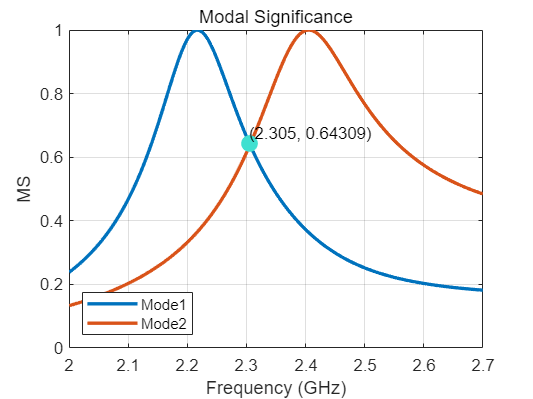

figure(fig_num)
plot(Freq/1e9, MS.data(:,2), LineWidth=2)
hold on
for i = 3:width(MS.data)
    %     if max(MS.data(:,i)) >= 0.5
    plot(Freq/1e9, MS.data(:,i), LineWidth=2)
    %     end
end
xlim([2, 2.7])

A = abs(MS.data(:,3)-MS.data(:,2));
sortedA = sort(A);
uniqueA = unique(sortedA);
secondSmallest = uniqueA(1);
secondSmallestIndex = find(A == secondSmallest);
index = secondSmallestIndex;

% [~, index] = min(abs(MWC.data(:,3)-MWC.data(:,2)));
MS_mode1 = MS.data(:,2);
MS_mode2 = MS.data(:,3);
xais_Freq = Freq/1e9;
% 标记给定x值在图形上
plot(xais_Freq(index), MS_mode1(index), 'o', 'MarkerEdgeColor', 'none',...
    'MarkerFaceColor',  [0.2500 0.8784 0.8157], 'MarkerSize', 10);
text(xais_Freq(index), MS_mode1(index), ...
    ['(' num2str(xais_Freq(index)) ', ' num2str(MS_mode1(index)) ')'], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom')

hold off
grid on
title(['Modal Significance'])
xlabel('Frequency (GHz)')
ylabel('MS')
legend('Mode1','Mode2', Location='southwest')

fig_num = fig_num +1;

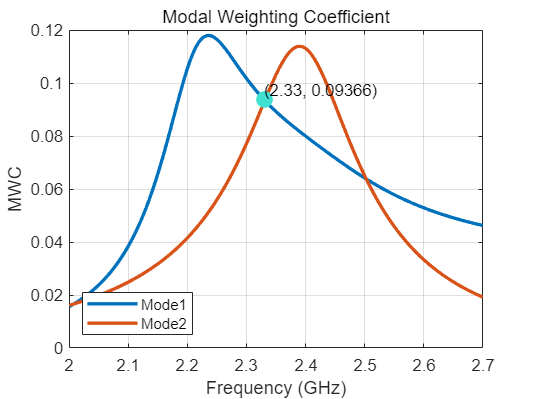

figure(fig_num)
plot(Freq/1e9, MWC.data(:,2), LineWidth=2)
hold on
for i = 3:width(MWC.data)
    %     if max(MS.data(:,i)) >= 0.5
    plot(Freq/1e9, MWC.data(:,i), LineWidth=2)
    %     end
end
xlim([2, 2.7])

A = abs(MWC.data(:,3)-MWC.data(:,2));
sortedA = sort(A);
uniqueA = unique(sortedA);
secondSmallest = uniqueA(6);
secondSmallestIndex = find(A == secondSmallest);
index = secondSmallestIndex;

% [~, index] = min(abs(MWC.data(:,3)-MWC.data(:,2)));
MWC_mode1 = MWC.data(:,2);
MWC_mode2 = MWC.data(:,3);
xais_Freq = Freq/1e9;
% 标记给定x值在图形上
plot(xais_Freq(index), MWC_mode1(index), 'o', 'MarkerEdgeColor', 'none',...
    'MarkerFaceColor',  [0.2500 0.8784 0.8157], 'MarkerSize', 10);
text(xais_Freq(index), MWC_mode1(index), ...
    ['(' num2str(xais_Freq(index)) ', ' num2str(MWC_mode1(index)) ')'], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom')


hold off
grid on
title(['Modal Weighting Coefficient'])
xlabel('Frequency (GHz)')
ylabel('MWC')
legend('Mode1','Mode2', Location='southwest')

fig_num = fig_num +1;

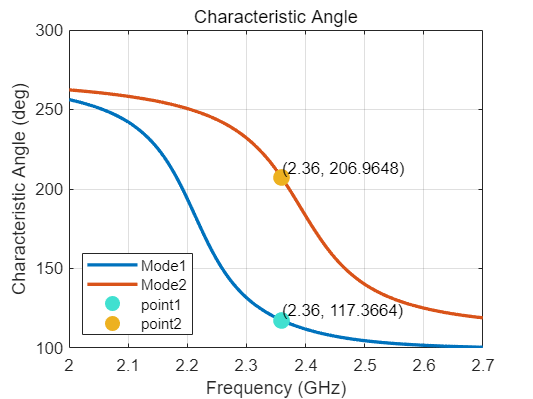

figure(fig_num)
plot(Freq/1e9, CA.data(:,2), LineWidth=2)
hold on
for i = 3:width(CA.data)
    %     if max(CA.data(:,i)) >= 0.5
    plot(Freq/1e9, CA.data(:,i), LineWidth=2)
    %     end
end
xlim([2, 2.7])
grid on
title(['Characteristic Angle'])
xlabel('Frequency (GHz)')
ylabel('Characteristic Angle (deg)')

[~, index] = min(abs(CA.data(:,3)-CA.data(:,2)-90));
CA_mode1 = CA.data(:,2);
CA_mode2 = CA.data(:,3);
xais_Freq = Freq/1e9;
% 标记给定x值在图形上
plot(xais_Freq(index), CA_mode1(index), 'o', 'MarkerEdgeColor', 'none',...
    'MarkerFaceColor',  [0.2500 0.8784 0.8157], 'MarkerSize', 10);
text(xais_Freq(index), CA_mode1(index), ...
    ['(' num2str(xais_Freq(index)) ', ' num2str(CA_mode1(index)) ')'], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom')
plot(xais_Freq(index), CA_mode2(index), 'o', 'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor','#EDB120', 'MarkerSize', 10);
text(xais_Freq(index), CA_mode2(index), ...
    ['(' num2str(xais_Freq(index)) ', ' num2str(CA_mode2(index)) ')'], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom')
hold off
fig_num = fig_num +1;
legend('Mode1','Mode2','point1', 'point2', Location='southwest')

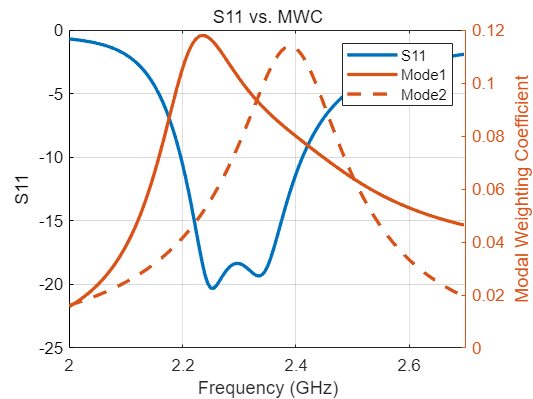

figure(fig_num)
plot(Freq/1e9, S11, LineWidth=2)
hold on
yyaxis right
for i = 2:width(MWC.data)
    if max(MWC.data(:,i)) >= 0.01
        plot(Freq/1e9, MWC.data(:,i), LineWidth=2)
    end
end
grid on
legend('S11', 'Mode1', 'Mode2')
yyaxis left
title('S11 vs. MWC')
xlabel('Frequency (GHz)')
ylabel('S11')
yyaxis right
ylabel('Modal Weighting Coefficient')
hold off
xlim([2, 2.7])

fig_num = fig_num +1;

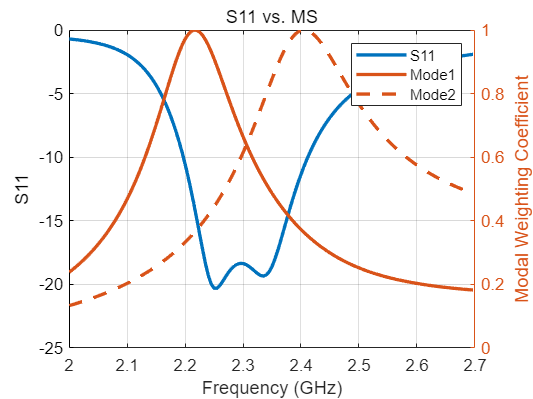

figure(fig_num)
plot(Freq/1e9, S11, LineWidth=2)
hold on
yyaxis right
for i = 2:width(MS.data)
    if max(MS.data(:,i)) >= 0.01
        plot(Freq/1e9, MS.data(:,i), LineWidth=2)
    end
end
grid on
legend('S11', 'Mode1', 'Mode2')
yyaxis left
title('S11 vs. MS')
xlabel('Frequency (GHz)')
ylabel('S11')
yyaxis right
ylabel('Modal Weighting Coefficient')
hold off
xlim([2, 2.7])

fig_num = fig_num +1;